    设$f\left(x\right)$是某个函数类$A$中给定的函数，要求在简单易算的函数类$B\subset A$时，求函数$s\left(x\right)$，使得$s\left(x\right)$与$f\left(x\right)$之差在某种度量意义下最小，这就是所谓的函数逼近问题。而平方逼近是指以下两种度量意义上的函数逼近

${\left\|f\left(x\right)-s\left(x\right)\right\|}_2 =\sqrt{\int_a^b {\left\lbrack f\left(x\right)-s\left(x\right)\right\rbrack }^2 \textrm{dx}}$                 (12-1)

${\left\|f\left(x\right)-s\left(x\right)\right\|}_2 =\sqrt{\sum_{i=0}^n {\left\lbrack f\left(x_i \right)-s\left(x_i \right)\right\rbrack }^2 }$            (12-2)

    其中，式(12-1)称为连续型的平方逼近，也称为**均方逼近**；式(12-2)称为离散性的平方逼近，通常称为**数据拟合**。

    从几何意义上讲，数据拟合问题等价于确定一条曲线，使它和试验数据点在某种意义上最接近。曲线拟合的目的是根据实验获得的数据去建立因变量和自变量之间的有效的经验函数关系，为进一步深入研究提供线索。

    本讲主要介绍**函数的最佳平方逼近**及**数据的最小二乘拟合**。

## **12.1   函数的最佳平方逼近**

设$\rho \textrm{（x）}$为[a,b]上的权函数，f为定义在[a,b]上的实值函数，定义f的范数

${\left\|f\right\|}_2 =\sqrt{\int_a^b \rho \textrm{（x）}{\left\lbrack f\left(x\right)\right\rbrack }^2 \textrm{dx}}$          (12-3)

令


$$L_{\rho }^2 \left\lbrack a,b\right\rbrack =\left\lbrace f\left|{\left\|f\right\|}_2 <\infty \right.\right\rbrace$$


称$L_{\rho }^2 \left\lbrack a,b\right\rbrack$是R上一个线性空间，若$\rho =1$，记为$L^2 \left\lbrack a,b\right\rbrack$.

    设$\varphi_0$,$\varphi_1$,$\varphi_2$,...,$\varphi_n$$\in$$L_{\rho }^2 \left\lbrack a,b\right\rbrack$，如果不存在n+1不全为零的数$c_i \textrm{（i}=0,1,\ldotp \ldotp \ldotp ,\textrm{n）}$，使


$${\left\|c_0 \varphi_1 +c_1 \varphi_1 +c_2 \varphi_2 +\ldotp \ldotp \ldotp +c_n \varphi_n \right\|}_2 =0$$


则称函数系{$\varphi_0$,$\varphi_1$,$\varphi_2$,...,$\varphi_n$}在$L_{\rho }^2 \left\lbrack a,b\right\rbrack$上线性无关。

     设$\varphi_0$,$\varphi_1$,$\varphi_2$,...,$\varphi_n$为$L_{\rho }^2 \left\lbrack a,b\right\rbrack$上线性无关的函数，记$\Phi =\textrm{span}\left\lbrace \varphi_0 ,\varphi_1 ,\varphi_2 ,\ldotp \ldotp \ldotp ,\varphi_n \right\rbrace$，则任取$s\in \Phi$有

$s\left(x\right)=\sum_{i=0}^n \alpha_i \varphi_i \left(x\right)$                         (12- 4)

    设$f\in L_{\rho }^2 \left\lbrack a,b\right\rbrack$，如果存在$s^{\ast } \in \Phi$使得

${\left\|f-s^{\ast } \right\|}_2^2 =\min_{s\in \Phi } {\left\|f-s\right\|}_2^2$              (12-5)

则称$s^{\ast }$为$f$在$\Phi$中的最佳平方逼近函数，下面来推导$s^{\ast }$。

    由 式(12-5) 可知，求解$s^{\ast }$即等价于求解多元函数


$$\textrm{I（}a_0 ,a_1 ,a_2 ,\ldotp \ldotp \ldotp ,a_n ）=\int_a^b \rho \left(x\right){\left\lbrack \sum_{i=0}^n a_i \varphi_i \left(x\right)-f\left(x\right)\right\rbrack }^2 \textrm{dx}$$


的极小值。由于$I\left(a_0 ,a_1 ,\ldotp \ldotp \ldotp ,a_n \right)$是关于$a_0 ,a_1 ,\ldotp \ldotp \ldotp ,a_n$的二次函数，因此，由多元函数极值的必要条件$\frac{\partial I}{\partial a_k }=0$可知

$\frac{\partial I}{\partial a_k }$=2$\int_a^b \rho \left(x\right)\left\lbrack \sum_{i=0}^n a_i \varphi_i \left(x\right)-f\left(x\right)\right\rbrack \varphi_k \left(x\right)\textrm{dx}=0\;\;\left(k=0,1,\ldotp \ldotp \ldotp ,n\right)$

于是有

$\sum_{i=0}^n \left(\varphi_k ,\varphi_i \right)a_i =\left(f,\varphi_k \right)\;\;\;\left(k=0,1,\ldotp \ldotp \ldotp ,n\right)$    (12-6)

将 式(12-6) 写成方程组的形式

$\left\lbrack \begin{array}{cccc}
\left(\varphi_0 ,\varphi_0 \right) & \left(\varphi_0 ,\varphi_1 \right) & \ldotp \ldotp \ldotp  & \left(\varphi_0 ,\varphi_n \right)\\
\left(\varphi_1 ,\varphi_0 \right) & \left(\varphi_1 ,\varphi_1 \right) & \ldotp \ldotp \ldotp  & \left(\varphi_1 ,\varphi_n \right)\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
\left(\varphi_n ,\varphi_0 \right) & \left(\varphi_n ,\varphi_1 \right) & \ldotp \ldotp \ldotp  & \left(\varphi_n ,\varphi_n \right)
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
\ldotp \ldotp \ldotp \\
a_n 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
\left(f,\varphi_0 \right)\\
\left(f,\varphi_1 \right)\\
\ldotp \ldotp \ldotp \\
\left(f,\varphi_n \right)
\end{array}\right\rbrack$   (12-7)

$\left(\alpha ,\beta \right)$表示内积，即

$\left(\alpha ,\beta \right)$=$\int_a^b \rho \left(x\right)\alpha \left(x\right)\beta \left(x\right)\textrm{dx}$         (12-8)

式(12-7) 或 式(12-8) 称为法方程组。

    由于$\varphi_0 ,\varphi_1 ,\varphi_2 ,\ldotp \ldotp ,\varphi_n$在$L_{\rho }^2 \left\lbrack a,b\right\rbrack$上线性无关，所以法方程组式(12-6)或式(12-7)的系数矩阵非奇异，于是法方程组有唯一解$\alpha_k =a_k^{\ast } ,k=0,1,2,\ldotp \ldotp \ldotp ,n,，$从而得到


$$s^{\ast } \left(x\right)=\sum_{i=0}^n a_i^{\ast } \varphi_i \left(x\right)$$


    下面证明$s^{\ast } \left(x\right)$满足$\sum_{i=0}^n \left(\varphi_k ,\varphi_i \right)a_i =\left(f,\varphi_k \right)\;\;\;\left(k=0,1,\ldotp \ldotp \ldotp ,n\right)$，即对任意$s\left(x\right)\in \Phi$有


$$\int_a^b \rho \left(x\right){\left\lbrack f\left(x\right)-s^{\ast } \left(x\right)\right\rbrack }^2 \textrm{dx}\le \int_a^b \rho \left(x\right){\left\lbrack f\left(x\right)-s\left(x\right)\right\rbrack }^2 \textrm{dx}$$


只要考虑


$$\begin{array}{l}
e=\int_a^b \rho \left(x\right){\left\lbrack f\left(x\right)-s\left(x\right)\right\rbrack }^2 \textrm{dx}-\int_a^b \rho \left(x\right){\left\lbrack f\left(x\right)-s^{\ast } \left(x\right)\right\rbrack }^2 \textrm{dx}\\
=\int_a^b \rho \left(x\right){\left\lbrack \left(f\left(x\right)-s^* \left(x\right)\right)+\left(s^* \left(x\right)-s\left(x\right)\right)\right\rbrack }^2 \textrm{dx}-\int_a^b \rho \left(x\right){\left\lbrack f\left(x\right)-s^{\ast } \left(x\right)\right\rbrack }^2 \textrm{dx}\\
=\int_a^b \rho \left(x\right){\left\lbrack s\left(x\right)-s^{\ast } \left(x\right)\right\rbrack }^2 \textrm{dx}+2\int_a^b \rho \left(x\right)\left\lbrack f\left(x\right)-s^{\ast } \left(x\right)\right\rbrack \left\lbrack s^{\ast } \left(x\right)-s\left(x\right)\right\rbrack \textrm{dx}\;
\end{array}$$


又


$$\begin{array}{l}
\int_a^b \rho \left(x\right)\left\lbrack f\left(x\right)-s^{\ast } \left(x\right)\right\rbrack \left\lbrack s^{\ast } \left(x\right)-s\left(x\right)\right\rbrack \textrm{dx}\\
=\int_a^b \rho \left(x\right)\left\lbrack f\left(x\right)-s^{\ast } \left(x\right)\right\rbrack \left\lbrack \sum_{i=0}^n a_i^* \varphi_i \left(x\right)-\sum_{i=0}^n a_i \varphi_i \left(x\right)\right\rbrack \textrm{dx}\\
=\sum_{i=0}^n \left(a_i^{\ast } -a_i \right)\int_a^b \rho \left(x\right)\left\lbrack f\left(x\right)-s^{\ast } \left(x\right)\right\rbrack \varphi_i \left(x\right)\textrm{dx}=0
\end{array}$$


因此


$$e=\int_a^b \rho \left(x\right){\left\lbrack s\left(x\right)-s^{\ast } \left(x\right)\right\rbrack }^2 \textrm{dx}+0\ge 0$$


这就证明了$s^{\ast } \left(x\right)$是$f\left(x\right)$在$\Phi$中的最佳平方逼近函数。

    根据式(12-7) 和式(12-8) 可以编写函数最佳平方逼近的程序square_approximation.m，具体内容如下：

function [A,B,p]=square_approximation(wfun,phifun,fun,a,b)

% 最佳平方逼近

% 输入参数：

%      ---wfun：权函数

%      ---phifun：基函数

%      ---fun：逼近函数

%      ---a,b：逼近区间的端点

%      ---n：最佳逼近的次数，默认值为1

% 输出参数：

%      ---A：法方程组的系数矩阵

%      ---b：法方程组的右端向量

%      ---p：最佳平方逼近的系数

n=size(phifun,1);

A=zeros(n);

for i=1:n

    for j=1:n

        f1=inline(['(',wfun,')','.*','(',phifun(i,:),')',...

            '.*','(',phifun(j,:),')']);

        A(i,j)=quad(f1,a,b);

    end

    f2=inline(['(',wfun,')','.*','(',phifun(i,:),')','.*','(',fun,')']);

    B(i)=quad(f2,a,b);

end

B=B';a=A\B;

p=a';

该函数的调用格式为：

[A,B,p]=square_approximation(wfun,phifun,a,b)

【例12-1】求函数$f\left(x\right)=e^x$在区间[-1,1]上的三次最佳平方逼近多项式。

解题方法：直接调用函数square_approximation()编写如下语句：

wfun='x.^0';  % 权函数
phifun=char('1','x','x.^2','x.^3');  % 基函数
fun='exp(x)';  % 被逼近函数
a=-1;b=1;  % 区间端点
[A,B,p]=square_approximation(wfun,phifun,fun,a,b)  % 求解三次最佳平方逼近多项式系数

A =     2.0000    0.0000    0.6667   -0.0000
    0.0000    0.6667         0    0.4000
    0.6667         0    0.4000         0
   -0.0000    0.4000         0    0.2857


B =     2.3504
    0.7358
    0.8789
    0.4495


p =     0.9963    0.9980    0.5367    0.1761


p2=poly2str(fliplr(p),'x')  % 根据多项式系数构造多项式

p2 = '   0.17614 x^3 + 0.53672 x^2 + 0.99795 x + 0.99629'

    因此三次最佳平方逼近多项式为


$$s_3^{\ast } \left(x\right)=0\ldotp 9963+0\ldotp 9980x+0\ldotp 5367x^2 +0\ldotp 1761x^3$$


    **说明：**根据函数文件square_approximation.m可知，这里要求的几个函数的书写方式均为字符串形式，而且wfun不能写成'1'，这需要注意。

## **12.2   数据的最小二乘拟合**

    在生产实践和科学实验中，经常会遇到大量的不同类型的数据，这些数据提供了有用的信息，可以帮助我们认识事物的内在规律，研究事物之间的关系等。

    已知关于自变量和因变量之间的一组数据$\left(x_i ,y_i \right),i=1,2,\ldotp \ldotp \ldotp ,n$,寻找一个合适类型的函数$y=f\left(x\right)$,使它在观测点$x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_n$处所取的值$f\left(x_{1\;} \right),f\left(x_2 \right),\ldotp \ldotp \ldotp ,f\left(x_n \right)$分别与观测值$y_1 ,y_2 ,\ldotp \ldotp ,y_n$在某种标准下充分接近。从而用$y=f\left(x\right)$作为观测点所反映规律的近似表达式，这一问题被称为**最佳曲线拟合问题**。

## 12.2.1  最小二乘法

    设有一系列实验数据$\left(x_i ,y_i \right),i=1,2,\ldotp \ldotp \ldotp ,m$以及各点的权系数$\rho \left(x_i \right)$（可以是实验的次数或者$y_i$的可信程度），要求在函数类$\Phi =\textrm{span}\left\lbrace \varphi_0 ,\varphi_1 ,\ldotp \ldotp \ldotp ,\varphi_n \right\rbrace$中求函数

$s^{\ast } \left(x\right)=\sum_{k=0}^n a_k^{\ast } \varphi_k \left(x\right)\;\;m\ge n$       (12-9)

满足

${\left\|\delta \right\|}_2^2 =\sum_{i=0}^m \rho \left(x_i \right){\left\lbrack s^{\ast } \left(x_i \right)-y_i \right\rbrack }^2 =\min_{s\in \Phi } \sum_{i=0}^m \rho \left(x_i \right){\left\lbrack s\left(x_i \right)-y_i \right\rbrack }^2$    (12-10)

式中**，**$s\left(x\right)=\sum_{k=0}^n a_k \varphi_k \left(x\right)$**为**$\Phi$**中任意函数，称这种函数近似表达式的方法为数据（曲线）的最小二乘拟合，称**$s^{\ast } \left(x\right)$**为最小二乘解**。

    在指定的函数$\Phi$中求拟合已知数据的最小二乘解的关键在于求系数$a_k^{\ast } \left(k=0,1,\ldotp \ldotp \ldotp ,n\right)$，使得$s^{\ast } \left(x\right)$满足式(12-2)，令

$I\left(a_0 ,a_1 ,\ldotp \ldotp \ldotp ,a_n \right)=\sum_{i=0}^m \rho \left(x_i \right){\left\lbrack s\left(x_i \right)-y_i \right\rbrack }^2 =\sum_{i=0}^m \rho \left(x_i \right){\left\lbrack \sum_{j=0}^n a_j \varphi_j \left(x_i \right)-y_i \right\rbrack }^2$  （12-11）

则$\left(a_0^{\ast } ,a_1^{\ast } ,\ldotp \ldotp \ldotp ,a_n^{\ast } \right)$是多元函数$I\left(a_0 ,a_1 ,\ldotp \ldotp \ldotp ,a_n \right)$取得极小值的点。

    由极值点的必要条件，数据的最小二乘拟合问题就转化为求解方程组

$\left\lbrack \begin{array}{cccc}
\left(\varphi_0 ,\varphi_0 \right) & \left(\varphi_0 ,\varphi_1 \right) & \ldotp \ldotp \ldotp  & \left(\varphi_0 ,\varphi_n \right)\\
\left(\varphi_1 ,\varphi_0 \right) & \left(\varphi_1 ,\varphi_1 \right) & \ldotp \ldotp \ldotp  & \left(\varphi_1 ,\varphi_n \right)\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
\left(\varphi_n ,\varphi_0 \right) & \left(\varphi_n ,\varphi_1 \right) & \ldotp \ldotp \ldotp  & \left(\varphi_n ,\varphi_n \right)
\end{array}\right\rbrack$$\left\lbrack \begin{array}{c}
a_0 \\
a_1 \\
\ldotp \ldotp \ldotp \\
a_n 
\end{array}\right\rbrack$=$\left\lbrack \begin{array}{c}
\left(f,\varphi_0 \right)\\
\left(f,\varphi_1 \right)\\
\ldotp \ldotp \ldotp \\
\left(f,\varphi_n \right)
\end{array}\right\rbrack$    （12-12）

式中

$\left(\varphi_j ,\varphi_k \right)=\sum_{i=0}^m \rho \left(x_i \right)\varphi_j \left(x_i \right)\varphi_k \left(x_i \right),\;\;\left(f,\varphi_k \right)=\sum_{i=0}^m \rho \left(x_i \right)y_i \varphi_k \left(x_i \right)$   （12-13）

称式（12-12）方程组为法方程组，当$\varphi_0 ,\varphi_1 ,\ldotp \ldotp \ldotp ,\varphi_n$线性无关时，方程组有唯一解$a_k =a_k^{\ast } ,k=0,1,2,\ldotp \ldotp \ldotp ,n$，于是有


$$s^{\ast } \left(x\right)=\sum_{k=0}^n a_k^{\ast } \varphi_k \left(x\right)$$


可以证明


$$\sum_{i=0}^m \rho \left(x_i \right){\left\lbrack s^{\ast } \left(x_i \right)-y_i \right\rbrack }^2 \le$$

$$\sum_{i=0}^m \rho \left(x_i \right){\left\lbrack s\left(x_i \right)-y_i \right\rbrack }^2$$


**最小二乘程序实现：**

根据式（12-12）和式（12-13）可以编写数据拟合的通用程序Least_square.m，具体内容如下：

function [A,b,p]=Least_square(wfun,phifun,x,y)

% 最小二乘拟合

% 输入参数：

%      ---wfun：权系数

%      ---phifun：拟合基函数

%      ---x,y：已知数据的x,y坐标

%      ---n：数据拟合的次数，默认值为1

% 输出参数：

%      ---A：法方程组的系数矩阵

%      ---b：法方程组的右端向量

%      ---p：最小二乘拟合系数

phifun=phifun(x);

n=size(phifun,1);

A=zeros(n);

for i=1:n

    for j=1:n

        A(i,j)=sum(wfun(i).*phifun(i,:).*phifun(j,:));

    end

    b(i)=sum(wfun(i).*phifun(i,:).*y);

end

b=b';

a=A\b;p= a';

    该函数的调用格式为;

[A,b,p]=Least_square(wfun,phifun,x,y)

【例12-2】  已知一组测量数据如下表所示，给定一组拟合函数$y=1,y=x,y=x^2 ,y=\textrm{cosx},y=e^x ,y=\textrm{sinx}$，试求其最小二乘拟合函数。

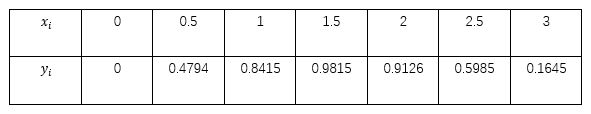

解：    调用Least_square()编写如下语句：

x=0:0.5:3;  % x轴数据
y=[0 0.4794 0.8415 0.9815 0.9126 0.5985 0.1645];  % y轴数据
wfun=ones(1,6);  % 权系数
phifun=@(x)[ones(size(x));x;x.^2;cos(x);exp(x);sin(x)];  % 拟合基函数
[A,b,p]=Least_square(wfun,phifun,x,y)  % 最小二乘拟合求解
syms x
digits(4)  % 设定精度
Phifun=[1;x;x.^2;cos(x);exp(x);sin(x)];
y=vpa(p*Phifun)  % 最小二乘拟合解函数

    最小二乘拟合函数为：


$$y=0\ldotp 3828+0\ldotp 4070x-0\ldotp 3901x^2 -0\ldotp 4598\cos \left(x\right)+0\ldotp 0765e^x +0\ldotp 5653\sin \left(x\right)$$


    **说明：**对于上面的问题，还可以通过以下简单语句求得相同的结果：

x=0:0.5:3;
y=[0 0.4794 0.8415 0.9815 0.9126 0.5985 0.1645];
A=[ones(size(x));x;x.^2;cos(x);exp(x);sin(x)];
p=y/A  %最小二乘法求解

【例12-3】  某化学反应，根据实验所得生成物的浓度与世间关系如下表所示，求浓度y与时间t的最小二乘拟合曲线。

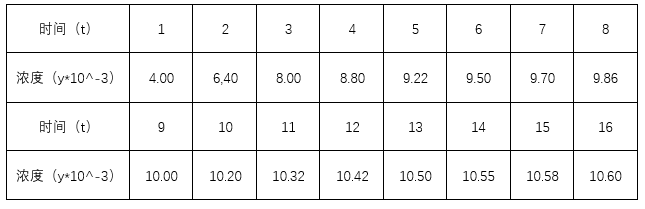

   解： 首先绘制实验数据的散点图，编写如下语句：

t=1:16;  % 时间
y=[4.00 6.40 8.00 8.80 9.22 9.50 9.70 9.86 10.00...
    10.20 10.32 10.42 10.50 10.55 10.58 10.60]*1e-3;  % 浓度
plot(t,y,'*')  % 绘制散点图

    由输出的散点图可以发现数据符合双曲线函数或者指数函数，下面分别就这两种函数原型进行拟合。

** --> ** **双曲线型：**$\frac{1}{y}=a+\frac{b}{t}$

    为确定a，b，调用函数Least_square()编写如下代码：

wfun=ones(1,2);  % 权系数
phifun=@(x)[ones(size(x));1./x];  % 拟合基函数
[A1,b1,p1]=Least_square(wfun,phifun,t,1./y)  % 最小二乘拟合求解

程序的输出结果为：

a=80.1745，b=162.7225。

    下面再编写如下语句求得双曲线型拟合所带来的误差：

F1=t./(fliplr(p1)*phifun(1./t));  % 拟合值
D1=y-F1;  % 误差
% 绝对值最大的误差
D1_max=max(abs(D1))  % D1_max=norm(D1,inf)
% 均方误差
D1_ME=norm(D1)

输出结果为：、

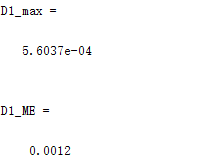

** --> ** **指数型：**$y=ae^{b/t}$，两边取自然对数有$\textrm{lny}=\ln \alpha +\frac{b}{t}$

    为确定a，b，调用函数Least_square()编写如下代码：

[A2,b2,p2]=Least_square(wfun,phifun,t,log(y))  % 最小二乘拟合求解

    程序的输出结果为：

    lna=-4.4807，b=-1.0567.

    下面再编写如下语句求得指数型拟合所带来的误差：

F2=exp(p2*phifun(t));  % 拟合值
D2=y-F2;  % 误差
% 绝对值最大的误差
D2_max=max(abs(D2))  % D2_max=norm(D2,inf)
% 均方误差
D2_ME=norm(D2)

程序的输出结果为：

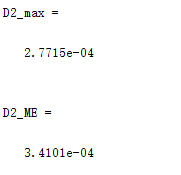

    比较上面两种函数原型的拟合误差发现：指数函数原型的拟合中绝对值最大的误差和均方误差都比较小，所以选用指数函数原型进行曲线拟合较好。

## 12.2.2  多元最小二乘拟合

曲面拟合问题也是实际工程应用中经常遇到的问题，这时可以将上面介绍到的最小二乘法的有关概念和结论推广到多元最小二乘法。已知m个自变量$\left(x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_m \right)$，一个因变量y的一组观测值$\left(x_{1i} ,x_{2i} ,\ldotp \ldotp \ldotp ,{x_{\textrm{mi}} ,y}_i \right)\left(i=1,2,\ldotp \ldotp \ldotp ,p\right)$及权系数$\rho_i >0$，要确定函数

$s_n^{\ast } \left(x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_m \right)=\sum_{k=1}^n a_k^{\ast } \varphi_k \left(x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_m \right)\;\;n\le p$    （12-14）

使得

$\sum_{i=1}^p \rho_i {\left\lbrack s_n^{\ast } \left(x_{1i} ,x_{2i} ,\ldotp \ldotp \ldotp ,x_{\textrm{mi}} \right)-y_i \right\rbrack }^2 =\min_{s_n \in \Phi } \sum_{i=1}^p \rho_i {\left\lbrack s_n \left(x_{1i} ,x_{2i} ,\ldotp \ldotp \ldotp ,x_{\textrm{mi}} \right)-y_i \right\rbrack }^2$    （12-15）

    下面来推导$s_n^{\ast } \left(x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_m \right)$，令

$I\left(a_0 ,a_1 ,\ldotp \ldotp \ldotp ,a_n \right)=\sum_{i=0}^m \rho_i {\left\lbrack s_n \left(x_{1i} ,x_{2i} ,\ldotp \ldotp \ldotp ,x_{\textrm{mi}} \right)-y_i \right\rbrack }^2$            （12-16）

则上述问题转化为多元函数的极值问题。

    与前面介绍的极值问题完全一样，$\left(a_0 ,a_1 ,\ldotp \ldotp \ldotp ,a_n \right)$同样满足法方程组，只是这里


$$\left(\varphi_k ,\varphi_j \right)=\sum_{i=0}^p \rho_i \varphi_k \left(x_{1i} ,x_{2i} ,\ldotp \ldotp \ldotp ,x_{\textrm{mi}} \right)\varphi_j \left(x_{1i} ,x_{2i} ,\ldotp \ldotp \ldotp ,x_{\textrm{mi}} \right)$$


求解法方程组则得到$s_n^{\ast } \left(x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_m \right)$，则称$s_n^{\ast } \left(x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_m \right)$为多元函数的最小二乘拟合函数。

## 12.2.3  数据拟合的MATLAB函数求解

    **MATLAB拟合工具箱**中提供了丰富的数据拟合求解函数，下面针对各种不同的情形介绍相应函数的用法。

   ** 1.线性拟合**

   ** 在多元最小二乘拟合中，若选取拟合基函数为**$x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_m ,1$**，则相应的拟合称为多元线性拟合**，对应的最小二乘拟合函数为


$$f\left(x_1 ,x_2 ,\ldotp \ldotp \ldotp ,x_m \right)=a_1 x_1 +a_2 x_2 +\ldotp \ldotp \ldotp +a_m x_m +a_{m+1}$$


将已知观测值$\left(x_{1i} ,x_{2i} ,\ldotp \ldotp \ldotp ,x_{\textrm{mi}} ,y_i \right)\left(i=1,2,\ldotp \ldotp \ldotp ,p\right)$代入上述函数模型中，可以得到方程组


$$y_i =a_1 x_{1i} +a_2 x_{2i} +\ldotp \ldotp \ldotp +a_m x_{\textrm{mi}} +a_{m+1} \;\;\;\;\left(i=1,2,\ldotp \ldotp \ldotp ,p\right)$$


上面的方程写成矩阵的形式为


$$\textrm{MX}=\mathit{\mathbf{d}}$$


$\textrm{其中M}=\left\lbrack \begin{array}{ccccc}
x_{11}  & x_{21}  & \ldotp \ldotp \ldotp  & x_{\textrm{m1}}  & 1\\
x_{12}  & x_{22}  & \ldotp \ldotp \ldotp  & x_{\textrm{m2}}  & 1\\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
x_{1p}  & x_{2p}  & \ldotp \ldotp \ldotp  & x_{\textrm{mp}}  & 1
\end{array}\right\rbrack$,$\mathit{\mathbf{X}}=\left\lbrack \begin{array}{c}
a_1 \\
a_2 \\
\ldotp \ldotp \ldotp \\
a_{m+1} 
\end{array}\right\rbrack$，**d**=$\left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
\ldotp \ldotp \ldotp \\
y_p 
\end{array}\right\rbrack$ 。

    对于该问题可以将它转化为下面的最小二乘优化问题


$$\min \;\frac{1}{2}{\left\|\textrm{MX}-\mathit{\mathbf{d}}\right\|}_2^2$$


    MATLAB最优化工具箱提供了函数 **lsqlin() **求解上述问题，下面用一个实例说明该函数的使用方法。

【例12-4】  已知一组观测数据，如下表所示，试对表中数据进行二元线性拟合。

    调用lsqlin()函数编写如下程序：

x=[0.1:0.1:0.9]';
y=[1.8 1.7 1.6 1.5 1.4 1.2 1 0.85 0.67]';
z=[5 5.2 5.8 6.3 5.7 5.9 6 7 7]';
M=[x y ones(size(x))];  % 构造矩阵M
X=lsqlin(M,z);  % 求解二元线性拟合问题
% X=M\z;     % 一种简单方法：求线性方程组最小二乘解
[xx,yy]=meshgrid(x,y);
z1=X(1)*xx+X(2)*yy+X(3);
mesh(xx,yy,z1)  % 绘制网格曲面图
hold on  % 图形保持
plot3(x,y,z,'ko')  % 绘制数据点
alpha(0.6)  % 设置透视程度

    程序的运行结果如图所示。

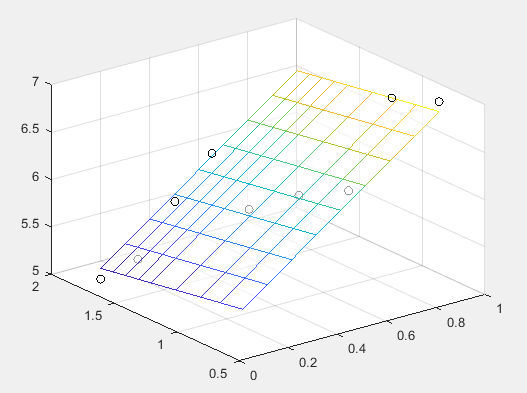

    **说明：**由上面的图形可以看出，平面的上面有五个点，下面有四个点。

    **2. 多项式拟合**

    在最小二乘拟合中，**当拟合基函数选取幂函数类**$1,x,x^2 ,\ldotp \ldotp \ldotp ,x^n$**时，相应的拟合称为多项式拟合**。

    MATLAB提供的 **polyfit()** 函数是专门用来求解多项式拟合的函数，其调用格式为：

[p,S]=polyfit(x,y,n) %格式1
[p,S,mu]=polyfit(x,y,n) %格式2

其中格式1是一般的多项式拟合，格式2是对x归一化处理后的多项式拟合，等价格式为：

[p,S]=polyfit((x-mean(x))/std(x),y,n)

x，y是输入的实验数据；mean(x)返回向量x的平均值，std(x)返回向量x的标准差，n是拟合计算用到的多项式的阶数；返回值p是拟合多项式系数；S是用来估计误差和预测数据的结构体；mu是由均值和标准差构成的1x2向量，即mu=[mean(x),std(x)]。

    与 **polyfit() **函数配合使用的函数是** polyval()**，这个函数是根据拟合出来的多项式系数p计算给定数据x处的y值。其调用格式如下：

[Y,DELTA]=polyval(p,X,S)
[Y,DELTA]=polyval(p,X,S,mu)

其中X是给定的需要计算拟合值的向量；p，S，mu是polyfit()函数的返回值；返回值Y是根据p计算出来的X处的多项式的值；DELTA是利用结构体S计算出来的误差估计，Y的95%置信区间为[Y-DELTA,Y+DELTA]，当DELATA缺省时，S可以为'[]'

【例12-5】 下表列出了2009年全国1~8月的股票交易成交金额的相关统计数据，试利用7次多项式拟合出曲线，以观察上海和深圳股票发展走势。

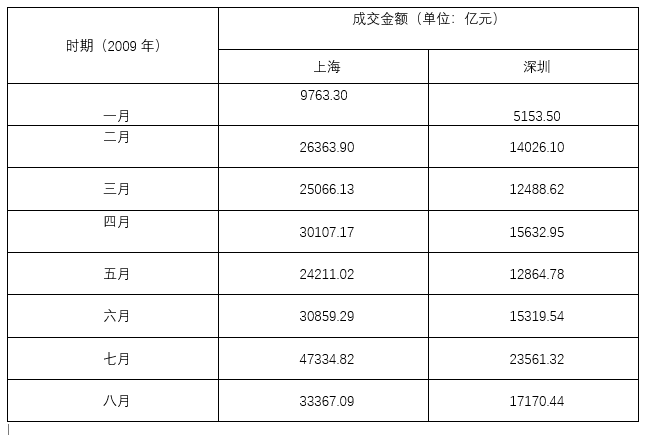

利用polyfit()函数编写如下语句：

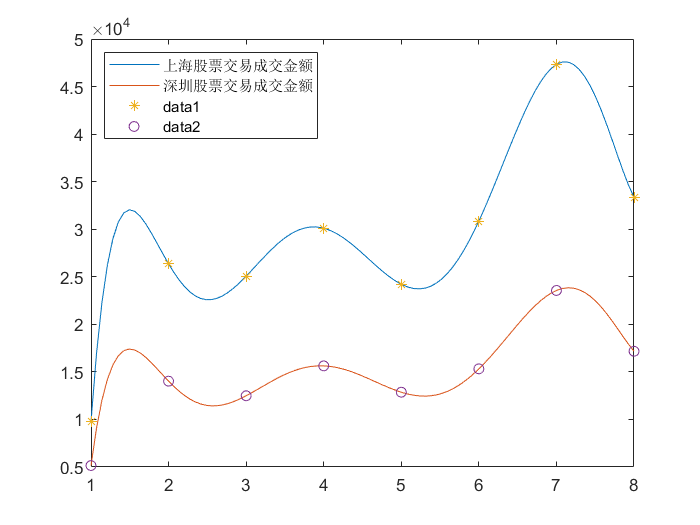

clf
yeah=1:8;
SH=[9763.30 26363.90 25066.13 30107.17 24211.02 30859.29 47334.82 33367.09];
SZ=[5153.50 14026.10 12488.62 15632.95 12864.78 15319.54 23561.32 17170.44];
%plot(yeah,SH,'*',yeah,SZ,'o')  % 绘制数据点
p1=polyfit(yeah,SH,7);      % 7次多项式拟合
p2=polyfit(yeah,SZ,7);      % 7次多项式拟合
t=linspace(1,8,100);  % 加密数据点
z1=polyval(p1,t);  % 求多项式的拟合值
z2=polyval(p2,t);  % 求多项式的拟合值
h=plot(t,z1,t,z2);
legend(h,'上海股票交易成交金额','深圳股票交易成交金额', 'Location' ,'northwest');
hold on 
plot(yeah,SH,'*',yeah,SZ,'o')  % 绘制数据点

【例12-6】  已知一组观察数据，如下表所示。试利用1~8次多项式拟合表中数据。

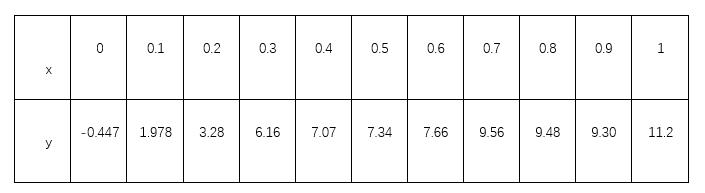

    编写如下程序代码

x=0:0.1:1;
y=[-0.447 1.978 3.28 6.16 7.07 7.34 7.66 9.56 9.48 9.30 11.2];
xi=linspace(0,1);
for k=1:8
    p=polyfit(x,y,k);  % 多项式拟合
    yp=polyval(p,xi);  % 求节点处的拟合值
    figure(k)
    plot(x,y,'ro',xi,yp,'k')  % 绘制图形
    for i=1:length(p)
        digits(5)  % 设置精度
        h1=text(0.08*i-0.03,i-2,['p(',num2str(i),')=',char(vpa(p(i)))]);  % 添加标注
        h2=text(0.95,i-2,['{\itx}^',num2str(length(p)-i)]);  % 添加标注
        set([h1,h2],'fontname','times','fontsize',12)  % 设置标注的字形与字号
        title([num2str(k),'次多项式'],'fontname','隶书','fontsize',16)  % 添加标题
    end
%     pause(1)  % 暂停1秒
end

程序最后的执行结果如下图所示。

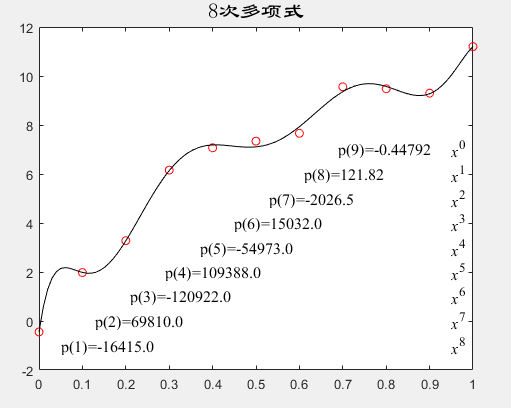

    **3. 非线性拟合**

    **在最小二乘拟合中，若要寻求的函数f(x)是任意的非线性函数，则称为非线性最小二乘拟合**，由该定义可知多项式拟合是一种特殊的非线性拟合。

    MATLAB**最优化工具箱**中提供了** lsqcurvefit() **函数，可以解决非线性最小二乘拟合问题，该函数的调用格式为：

[x,resnorm,residual,exitflag,output,lambda,jacobian]=lsqcurvefit(fun,x0,xdata,ydata,...

    lb,ub,options,p1,p2,...)

其中，fun是非线性函数模型；x0是最优化的初始值；xdata，ydata是原始输入输出数据向量；返回值x为拟合输出的未知参数，其他参数的含义可查询帮助文档。

【例12-7】  在一次传染病中，已知t时刻的人数i(t)满足如下模型$i\left(t\right)=\frac{1}{a+be^{\textrm{ct}} }$，公共部门每隔5天记录一次传染者的人数，具体见下表，试建立回归模型求出a,b,c。

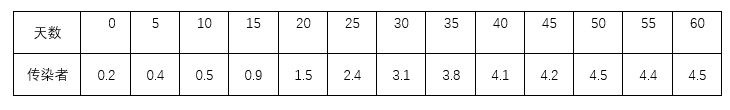

调用** lqscurvefit() **函数求解该题，编写如下代码：

t=0:5:60;
y=[0.2 0.4 0.5 0.9 1.5 2.4 3.1 3.8 4.1 4.2 4.5 4.4 4.5];
f=@(b,x)1./(b(1)+b(2)*exp(b(3)*x));  % 定义拟合函数模型
x = lsqcurvefit(f,[0.5,10,0],t,y)  % 最小二乘拟合求解


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


x =     0.2214    7.3797   -0.1440


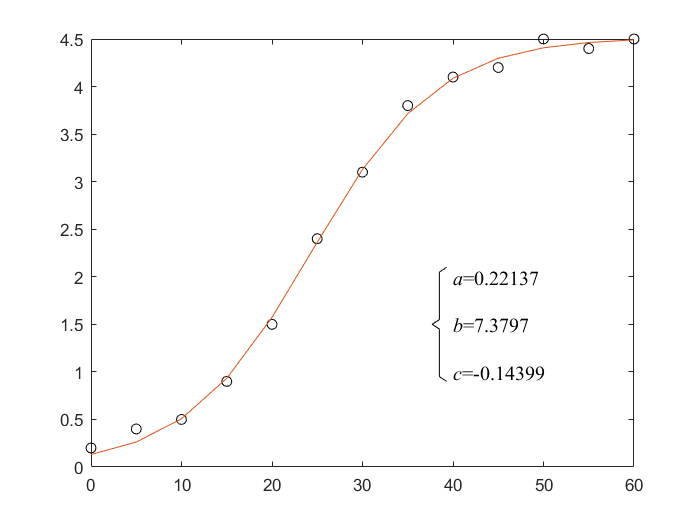

clf
plot(t,y,'ko',t,f(x,t))  % 绘制图形
hold on  % 图形保持
plot([39.3,38.5,38.5,37.7,38.5,38.5,39.3],...
    [2.1,2.05,1.55,1.5,1.45,0.95,0.9],'k')  % 绘制左括弧
h(1)=text(40,2,['{\ita}=',num2str(x(1))]);  % 添加标注
h(2)=text(40,1.5,['{\itb}=',num2str(x(2))]);  % 添加标注
h(3)=text(40,1,['{\itc}=',num2str(x(3))]);  % 添加标注
set(h,'fontname','times','fontsize',12)  % 设置标注的字号与字形

**    4.多元非线性拟合**

    MATLAB统计工具箱中提供的求解多元非线性回归的函数nlinfit()可以满足要求，该函数的调用格式为;

[bata,r,J]=nlinfit(X,y,fun,beta0,options)

其中beta是返回的回归系数，这里也就是拟合系数，r是残差，J是Jacobian矩阵；输入数据x、y分别为mn矩阵和n维列向量，对一元非线性回归x为n维列向量；fun是回归模型的数学表达式，beta0是预先设定的回归系数初值，options是控制参数选项，它可以通过statset()函数来设置，至于相关的属性及属性名可参阅帮助文档。

【例12-8】  反应动力学中的Hougen-Watson模型是非线性模型的一个典型例子，其模型如下


$$y=\frac{\beta_1 x_2 -x_3 /\beta_5 }{1+\beta_2 x_1 +\beta_3 x_2 +\beta_4 x_3 }$$


其中，y为反应速率，其三个决定因素分别为$x_1 \textrm{（氢气），}x_2 \textrm{（n}-\textrm{戊烷），}x_3 \textrm{（异戊烷）}$，下表是一组实验数据，试建立回归模型，求出未知参数$\beta_i \left(i=1,2,3,4,5\right)$。

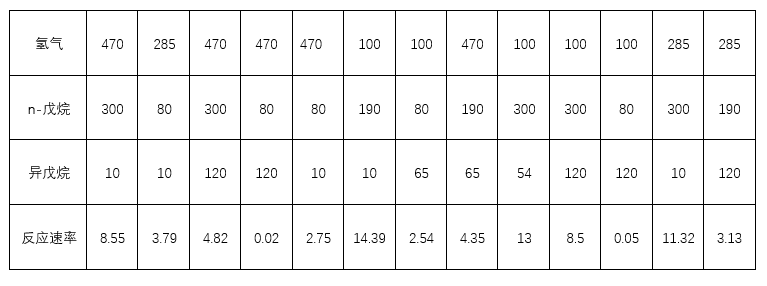

    编写如下代码：

reactants =[470 285 470 470 470 100 100 470 100 100 100 285 285;
              300 80 300 80 80 190 80 190 300 300 80 300 190;
              10 10 120 120 10 10 65 65 54 120 120 10 120]';  % 反应物
rate =[8.55,3.79,4.82,0.02,2.75,14.39,2.54,4.35,13,8.5,0.05,11.32,3.13]';  % 反映速率
f=@(b,x)(b(1)*x(:,2)-x(:,3)/b(5))./(1+b(2)*x(:,1)+b(3)*x(:,2)+b(4)*x(:,3));  % 定义拟合函数
b0=[1;0.1;0.2;0.1;2];  % 初始值
betafit = nlinfit(reactants,rate,f,b0)  % 回归系数求解

betafit =     1.2526
    0.0628
    0.0400
    0.1124
    1.1914


## 12.3  实验范例：薄膜渗透率的测定

    1）问题的提出

    某种医用薄膜允许一种物质分子穿透它，从高浓度的溶液向低浓度的溶液扩散，在试制时需测定薄膜被这种分子穿透的能力。测定方法如下：用面积为S的薄膜将容器分成体积分别为$V_A ，V_B$的两部分，如下图所示，该物质的两种不同浓度的溶液，此时该物质的分子就会从高浓度溶液穿过薄膜向低浓度溶液扩散。通过单位面积膜分子扩散速度与膜两侧溶液的浓度差成正比，比例**系数K表征了薄膜被该分子穿透的能力，称为渗透率。定时测量容器中薄膜某一侧的浓度值，以此确定K的数值**。

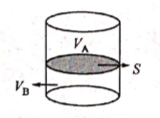

    2）模型的建立

    这是一个综合性的应用实例，主要涉及微分方程和数据拟合参数（即参数辨识）的数学知识。

   ** 模型假设**

    为叙述方便，作如下假设：

    （1）薄膜两侧的溶液始终是均匀的。即在任何时刻薄膜两侧的每一处溶液的浓度都是相同的。

    （2）当两容器浓度不一致时，物质的分子总是穿透薄膜从高浓度溶液向低浓度溶液扩散。

    （3）通过单位面积膜分子扩散的速度与膜两侧溶液的浓度差成正比。

    （4）薄膜是双向同性的，即物质从膜的任何一侧向另一侧渗透的性能是相同的。

    **符号说明**

    （1）$C_A \left(t\right),C_B \left(t\right)$表示$t$时刻膜两侧溶液的浓度；

    （2）$a_A ，a_B$表示初始时刻两侧溶液的浓度（单位：$\textrm{mg}/{\textrm{cm}}^3$）；

    （3）*K*表示渗透率；

    （4）$V_A ,V_B$表示由薄膜阻隔的容器两侧的体积。

    **问题分析**

    考察时段$\left\lbrack t,t+\Delta t\right\rbrack$薄膜两侧容器中该物质质量的变化。以容器A侧为例，在该时段物质质量的增加量为$V_A C_A \left(t+\Delta t\right)-V_A C_A \left(t\right)$,另一方面从B侧渗透至A侧的该物质的质量为$\textrm{SK}\left(C_B -C_A \right)\Delta t$。由质量守恒定律，两者应该相等，于是有


$$V_A C_A \left(t+\Delta t\right)-V_A C_A \left(t\right)=\textrm{SK}\left(C_B -C_A \right)\Delta t$$


两边除以$\Delta t$，令$\Delta t\to 0$并整理得


$$\frac{dC_A }{\textrm{dt}}=\frac{\textrm{SK}}{V_A }\left(C_B -C_A \right)$$


且注意到整个容器的溶液中含有该物质的质量应该不变，即有下式成立


$$\begin{array}{l}
V_A C_A \left(t\right)+V_B C_B \left(t\right)=V_A \alpha_A +V_B \alpha_B \\
\Rightarrow C_A \left(t\right)=\alpha_A +\frac{V_B }{V_A }\alpha_B -\frac{V_B }{V_A }C_B \left(t\right)
\end{array}$$


代入得


$$\frac{dC_B }{\textrm{dt}}+\textrm{SK}\left(\frac{1}{V_A }+\frac{1}{V_B }\right)C_B =\textrm{SK}\left(\frac{\alpha_A }{V_B }+\frac{\alpha_B }{V_A }\right)$$


再利用初始条件$C_B \left(0\right)=\alpha_B$，解出


$$C_B \left(t\right)=\frac{V_A \alpha_A +V_B \alpha_B }{V_A +V_B }+\frac{V_A \left(\alpha_B -\alpha_A \right)}{V_A +V_B }e^{-\textrm{SK}\left(\frac{1}{V_A }+\frac{1}{V_B }\right)t}$$


    至此，问题归结为利用$C_B$在时刻$t_i$的测量数据$C_j \left(j=1,2,\ldotp \ldotp \ldotp ,N\right)$来辨识参数$K$和$\alpha_A ,\alpha_B$，对应的数学模型变为求函数


$$E\left(K,a_A ,a_B \right)=\sum_{j=1}^N {\left\lbrack C_B \left(t_j \right)-C_j \right\rbrack }^2$$


的极小值。

令


$$\begin{array}{l}
a=V_A \alpha_A +V_B \alpha_B \\
b=V_A \left(\alpha_B -\alpha_A \right)
\end{array}$$


则问题转化为求函数


$$E\left(K,a,b\right)=\sum_{j=1}^N {\left\lbrack \frac{a}{V_A +V_B }+\frac{b}{V_A +V_B }e^{-\textrm{SK}\left(\frac{1}{V_A }+\frac{1}{V_B }\right)t} -C_j \right\rbrack }^2$$


的最小值点（K，a，b）。

    3）模型的求解

    设$V_A =V_B =1000{\textrm{cm}}^3 ,S=10{\textrm{cm}}^3$，对容器B的部分溶液浓度的测试结果如下表所示。

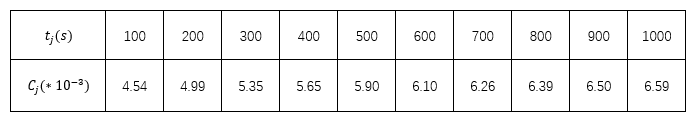

其中$C_j$的单位为$\textrm{mg}/{\textrm{cm}}^3$。

下面编写如下程序：

syms t S K VA VB aA aB;
s=dsolve('Dy+S*K*(1/VA+1/VB)*y=S*K*(aA/VB+aB/VA)','y(0)=aB');  % 微分方程求解

fun=char(s);  % 将符号表达式转换为字符串
fun(findstr(fun,' '))=[];  %将字符串的空格去掉
fun=strrep(fun,'VA*aA+VB*aB','x(1)');  % 执行替换操作
fun=strrep(fun,'VA*aA-VA*aB','x(2)');  % 执行替换操作
fun=strrep(fun,'K','x(3)');  % 执行替换操作
fun=inline(fun,'x','t','VA','VB','S');  % 将字符串转换为内联函数
fun=vectorize(fun);  % 乘、除、指数运算转换为对应的点操作，此处可省略
format long
td = linspace(100,1000,10);
Cd =1e-5*[4.54,4.99,5.35,5.65,5.90,6.10,6.26,6.39,6.50,6.59];
x0 =0.05*ones(1,3);
VA=1000;VB=1000;S=10;
x=nlinfit(td,Cd,@(x,t)fun(x,t,VA,VB,S),x0)  % 回归模型求解

x =    0.139700807548691   0.059881506156842   0.101227381591706


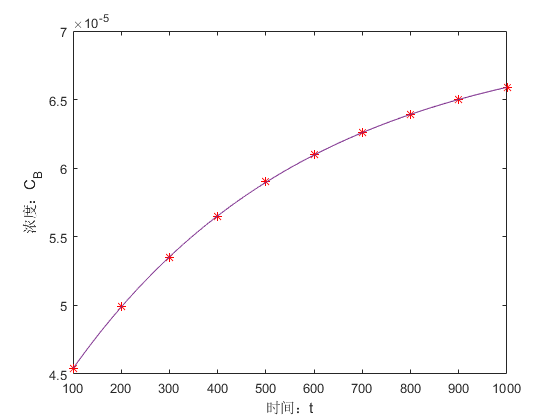

% nlintool(td,Cd,@(x,t)fun(x,t,VA,VB,S),x0,[],'时间：t','浓度：C_B')
plot(td,Cd,'r*')  % 绘制数据点
hold on  % 图形保持
tp=linspace(min(td),max(td),200);
yp=fun(x,tp,VA,VB,S);
plot(tp,yp)
xlabel('时间：t');ylabel('浓度：C_B');  % 添加x轴和y轴标注

a=[VA,VB;-VA,VA]\x(1:2)'  % 利用线性方程组求aA,aB

a = 	1.0e+-4 *

   0.399096506959245
   0.997911568527663


作业：

1、设$f\left(x\right)=xe^x ,x\in \left\lbrack 0,1\ldotp 5\right\rbrack$，求f(x)的三次近似最佳平方逼近多项式

2、已知一组观测数据$\left(x_i ,y_i \right)$见下表，函数的原型为$y=a_1 +a_2 x^2 +a_3 e^{-5x^3 } +a_4 \cos \left(-2x\right)+a_5 x^4$，试用所给数据求出待定系数$a_i$的值。